# Numerical Analysis Project 1

Nathaniel Valla

format long


$$f(X,K,N,D) = x_i\bigg(1+\sum_{j=1}^M \frac{\kappa_{ij}\eta_{j}}{1+\sum_{s=1}^N \kappa_{sj}x_i}\bigg) -\xi_i 
$$
 

The function $f(X,K,N,D)
$ takes a vector of x value  with a maktrix $\kappa
$ as K, vector $\eta $ as N, and another vector $\xi
$as D.

It produces two vector of one of the value of the vector x and its derivative

The function $newtons(X,K,N,D)$  takes in the sample parameters as $f(X,K,N,D)
$ then preforms newtons method to find the root

The function $bisection(X,Y,K,N,D)$  takes in the sample parameters as $f(X,K,N,D)
$ with a second  x vector to preform bisection

The function $fixpntit(X,Y,K,N,D)$  takes in the sample parameters as $f(X,K,N,D)
$ preforms fixed point interation

The function $graph(K,N,D)$  takes in the sample parameters K,N, and D and   graphs$f(X,K,N,D)
$

Test 1)

eta    = 10;
kappa = 1 ;
xi = 1;
graph(kappa,eta,xi)

r_n = newtons(1,kappa,eta,xi);
r_b = bisection(0,2,kappa,eta,xi);
r_f = fixpntit(1,kappa,eta,xi);
[~,np] = f(r_b,kappa,eta,xi);
fprintf("The root found using Newtons methods is %d\n" + ...
        "The root found using bisection is %d\n" +...
        "The root found using fixed point iteration is %d\n"+ ...
        "The derivative at root found using besection%d",r_n,r_b,r_f,np);

The root found using Newtons methods is 9.901951e-02
The root found using bisection is 9.901951e-02
The root found using fixed point iteration is 8.185358e+01
The derivative at root found using besection9.279216e+00

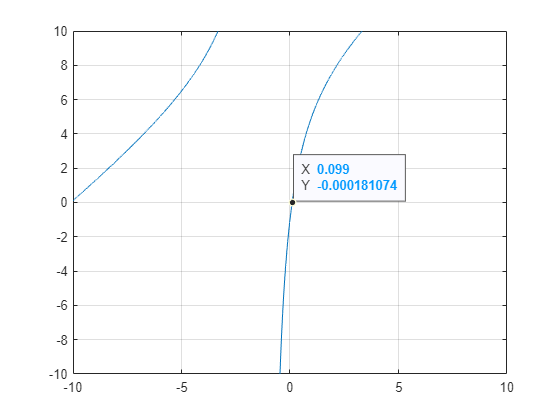

ax = gca;
chart = ax.Children(1);
datatip(chart,r_b,f(r_b,kappa,eta,xi));

Test 2)

eta   = [2,3,1];
kappa = [1,2,6];
xi    = 9;

graph(kappa,eta,xi)

r_n = newtons(3.907,kappa,eta,xi);
r_b = bisection(2,4,kappa,eta,xi);
r_f = fixpntit(1,kappa,eta,xi);
fprintf("The root found using Newtons methods is %d\n" + ...
        "The root found using bisection is %d\n" +...
        "The root found using fixed point iteration is %d\n"+ ...
        "The derivative at root found using besection %d",r_n,r_b,r_f,np);

The root found using Newtons methods is 3.806383e+00
The root found using bisection is 3.806383e+00
The root found using fixed point iteration is -2.745887e+01
The derivative at root found using besection 9.279216e+00

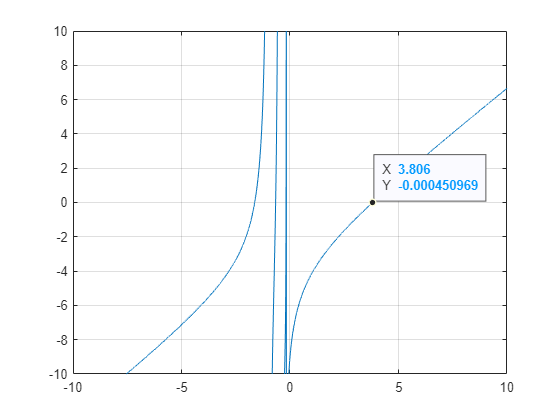

ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,r_b,f(r_b,kappa,eta,xi));

Test 3)

eta   = 6;
kappa = 5;
xi    = 7;
graph(kappa,eta,xi)

r_n = newtons(0.2,kappa,eta,xi);
r_b = bisection(0,2,kappa,eta,xi);
r_f = fixpntit(1,kappa,eta,xi);
fprintf("The root found using Newtons methods is %d\n" + ...
        "The root found using bisection is %d\n" +...
        "The root found using fixed point iteration is %d\n"+ ...
        "The derivative at root found using besection %d",r_n,r_b,r_f,np);

The root found using Newtons methods is 1.649000e+00
The root found using bisection is 1.649000e+00
The root found using fixed point iteration is -9.233258e+01
The derivative at root found using besection 9.279216e+00

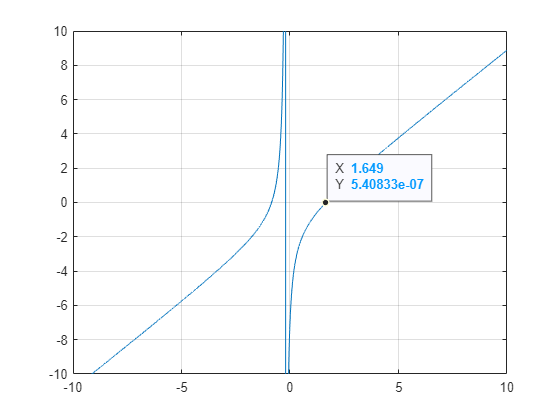

ax3 = gca;
chart3 = ax3.Children(1);
datatip(chart3,r_b,f(r_b,kappa,eta,xi));

Test 4)

eta   = [6,3];
kappa = [1,8];
xi    = 3;
graph(kappa,eta,xi)
r_n = newtons(0.2,kappa,eta,xi);
r_b = bisection(0,2,kappa,eta,xi);
r_f = fixpntit(1,kappa,eta,xi);
fprintf("The root found using Newtons methods is %d\n" + ...
        "The root found using bisection is %d\n" +...
        "The root found using fixed point iteration is %d\n"+ ...
        "The derivative at root found using besection %d",r_n,r_b,r_f,np);

The root found using Newtons methods is 1.947514e-01
The root found using bisection is 1.947514e-01
The root found using fixed point iteration is 5.393736e+01
The derivative at root found using besection 9.279216e+00

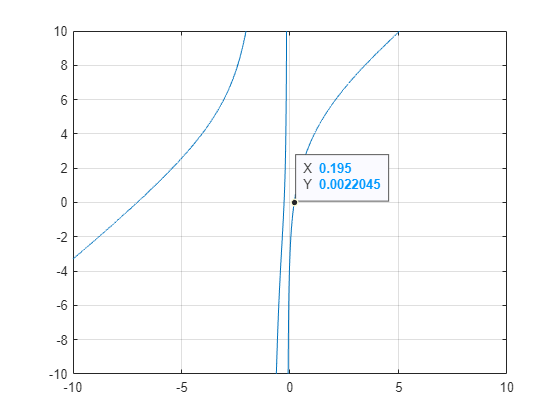

ax4 = gca;
chart4 = ax4.Children(1);
datatip(chart4,r_b,f(r_b,kappa,eta,xi));

### Conclusion 

Four test of root finding where performed. Two done with vectors of $\kappa,\eta$ and $\xi
$ provided in documentation, and two generated by the Random vector generator below. Three method where preform newtons method, bisection, and fixed point iteration. In all four tests newtons method and bisection both converged  to root, and fixed point iteration failed to find the root. On further analysis  it was that the derivative at the root is greater then one. This makes sense the fixed point iteration failed in each test in acourdance with the fixed point theroem. Fixed point iteration is cannot  be use to find the roots. Both bisesction and Newton methods are capable of finding these root. Bisection by defination convergers to the root linearly, but Newton method since the derivative at the root is non zero  it converges to root at least quadradically. I would suggest using Newtons methods on professor Ross problem.

#### Random Vector Generator

seed  = randi(10,1);
eta   = randi(10,1,seed);
kappa = randi(10,1,seed);
xi    = randi(10,1);

function graph(K,N,D)
    bond = 10;
    t = -bond:.001:bond ;
    y = zeros(1,size(t,2));
    for i = 1:size(t,2)
        y(i) = f(t(i),K,N,D);
    end

    figure
    plot(t,y);
    ylim([-bond,bond]);
    xlim([-bond,bond]);
    grid on
end
